BÁO CÁO THỰC HÀNH LAB 2

Họ và tên: Lê Hoàng Nam   MSSV: 21207246

Câu 1: Phân tích đoạn chương trình mẫu ở mục 1.1.3 ?

clear;clc
bitstream = [0 1 0 0 1 1 0 0 0 1 0];
pulse_high = 5;
pulse_low = 0;
for bit = 1:length(bitstream)
    % set bit time
    bt = bit-1:0.001:bit;
    if bitstream(bit) == 0
        % low level pulse
        y = (bt<bit)*pulse_low;
    else
        % high level pulse
        y = (bt<bit) * pulse_high;
    end
    
    try
        if bitstream(bit+1) == 1
            y(end) = pulse_high;
        end
    catch e
        % assume next bit is 1
        y(end) = pulse_high;
    end
    
    % draw pulse and label
    figure(1)
    plot(bt, y, 'LineWidth', 2);
    text(bit-0.5,pulse_high+0.5, num2str(bitstream(bit)), 'FontWeight', 'bold');
    hold on;
end

% draw grid
 grid on;
 axis([0 length(bitstream) pulse_low-1 pulse_high+1]);
 set(gca,'YTick', [pulse_low pulse_high])
 set(gca,'XTick', 1:length(bitstream))
 title('Unipolar Non-Return-to-Zero Level')

Câu 2: Thay đổi chuỗi dữ liệu toàn bit “0” quan sát và vẽ tín hiệu sau điều biến?

clear;clc
bitstream = [ 0 0 0 0 0 0 0 0 0 0 0];
pulse_high = 5;
pulse_low = 0;
for bit = 1:length(bitstream)
    % set bit time
    bt = bit-1:0.001:bit;
    if bitstream(bit) == 0
        % low level pulse
        y = (bt<bit)*pulse_low;

    else
        % high level pulse
        y = (bt<bit) * pulse_high;
    end
    
    try
        if bitstream(bit+1) == 1
            y(end) = pulse_high;
        end
    catch e
        % assume next bit is 1
        y(end) = pulse_high;
    end
    
    % draw pulse and label
    plot(bt, y, 'LineWidth', 2);
    text(bit-0.5,pulse_high+0.5, num2str(bitstream(bit)), 'FontWeight', 'bold');
    hold on;
end

% draw grid
 grid on;
 axis([0 length(bitstream) pulse_low-1 pulse_high+1]);
 set(gca,'YTick', [pulse_low pulse_high])
 set(gca,'XTick', 1:length(bitstream))
 title('Unipolar Non-Return-to-Zero Level')

Câu 3: Thay đổi dữ liệu toàn bit “1” quan sát và vẽ tín hiệu sau điều biến?

clear;clc
bitstream = [ 1 1 1 1 1 1 1 1 1 1];
pulse_high = 5;
pulse_low = 0;
for bit = 1:length(bitstream)
    % set bit time
    bt = bit-1:0.001:bit;
    if bitstream(bit) == 0
        % low level pulse
        y = (bt<bit)*pulse_low;

    else
        % high level pulse
        y = (bt<bit) * pulse_high;
    end
    
    try
        if bitstream(bit+1) == 1
            y(end) = pulse_high;
        end
    catch e
        % assume next bit is 1
        y(end) = pulse_high;
    end
    
    % draw pulse and label
    plot(bt, y, 'LineWidth', 2);
    text(bit-0.5,pulse_high+0.5, num2str(bitstream(bit)), 'FontWeight', 'bold');
    hold on;
end

% draw grid
 grid on;
 axis([0 length(bitstream) pulse_low-1 pulse_high+1]);
 set(gca,'YTick', [pulse_low pulse_high])
 set(gca,'XTick', 1:length(bitstream))
 title('Unipolar Non-Return-to-Zero Level')

Câu 4: Từ chương trình mẫu 1.1.3, thay đổi “pulse_low = -5”, quan sát và vẽ tín hiệu sau mã hóa?

clear;clc
bitstream = [ 0 1 0 0 1 1 0 0 0 1 0];
pulse_high = 5;
pulse_low = -5;
for bit = 1:length(bitstream)
    % set bit time
    bt = bit-1:0.001:bit;
    if bitstream(bit) == 0
        % low level pulse
        y = (bt<bit)*pulse_low;
    else
        % high level pulse
        y = (bt<bit) * pulse_high;
    end

    try
        if bitstream(bit+1) == 1
            y(end) = pulse_high;
        else
            y(end) = pulse_low;
        end
    catch e
        % assume next bit is 1
        y(end) = pulse_high;
    end

    % draw pulse and label
    plot(bt, y, 'LineWidth', 2);
    text(bit-0.5,pulse_high+0.5, num2str(bitstream(bit)), 'FontWeight', 'bold');
    hold on;
end

% draw grid
grid on;
axis([0 length(bitstream) pulse_low-1 pulse_high+1]);
set(gca,'YTick', [pulse_low pulse_high])
set(gca,'XTick', 1:length(bitstream))
title('Polar Non-Return-to-Zero Level')

Câu 5: Phân tích đoạn chương trình mẫu ở mục 1.1.4?

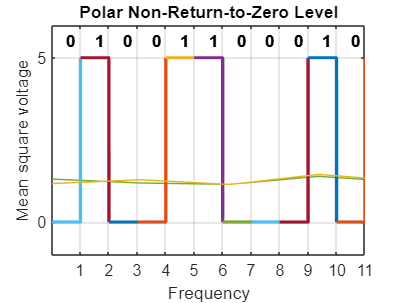

clear ; clc
bitstream = randi([0 1], 1, 10000);
fb=100;
pulse_high = 1;
pulse_low = -1;
yy=[];

for bit = 1:length(bitstream)
    % set bit time
    bt = bit-1:0.25:(bit-0.25);
    if bitstream(bit) == 0
        % low level pulse
        y = (bt<bit)*pulse_low;

    else
        % high level pulse
        y = (bt<bit) * pulse_high;
    end
    yy=[yy y];
end

k=zeros(100,400);
for j=1:1:100
    k(j,:)=yy(400*j-399:400*j);
    sep(j,:)=fft(k(j,:),128);
end
n=size(sep,2);
fs=4*fb;
f = (0:n-1)*(fs/n); % frequency range

m_sep=mean((abs(sep).^2),1)/fs;
figure(1);
plot(f,m_sep);
% draw grid
grid on;
ylabel('Mean square voltage');
xlabel('Frequency');
title('Polar Non-Return-to-Zero Level');

Câu 7: Hoàn thiện chương trình thực hiện mã hóa Bipolar-AMI?

Câu 8: Vẽ phổ tín hiệu mã hóa Bipolar-AMI?

Câu 9: Hoàn thiện chương trình thực hiện mã hóa Manchester?

Câu 10: Vẽ phổ tín hiệu mã hóa Manchester?